# Assignment 4: EEG Data Preprocessing with EEGLAB

## 1. Download the EEG data from the proved link.

% https://drive.google.com/file/d/1DeHj9WgkKhDr6Qni-EGfN4hybNDfSruq/view?usp=sharing

## 2. Import the data into MATLAB using EEGLAB functions.

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.8.1 to the path
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.8 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.0 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.7.1 (see >> help eegplugin_firfilt)


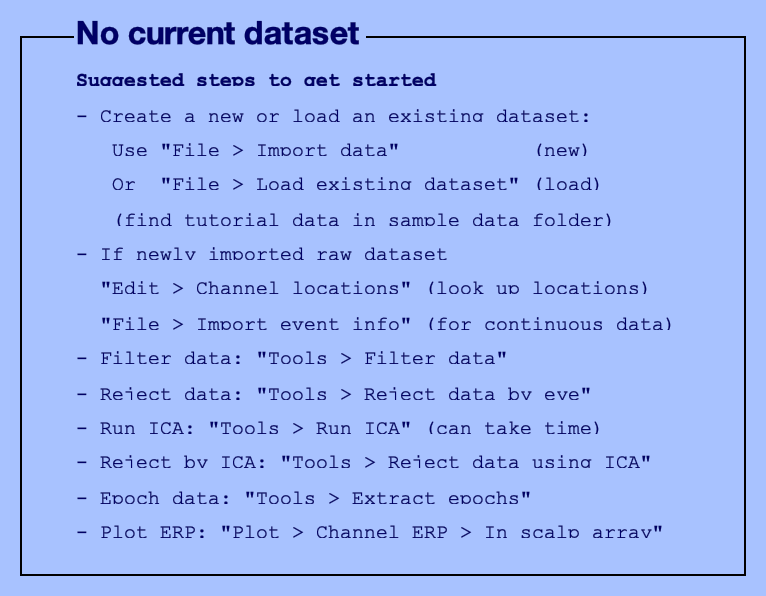

You are using the latest version of EEGLAB.


% 啟動 EEGLAB
eeglab;


% 設定數據文件的完整路徑
dataPath = '/Users/ninachiu/Documents/GitHub/2023_Summer_Workshop/1. Matlab and EEGlab';
dataFile = 'A01E.gdf';
fullDataPath = fullfile(dataPath, dataFile);

% 使用 EEGLAB 函數導入數據
EEG = pop_biosig(fullDataPath);

sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in GDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Detected/removing 'EEG' prefix from channel labels


Importing data events...
eeg_checkset note: event field format 'edfplustype' made uniform
eeg_checkset note: creating the original event table (EEG.urevent)



% 顯示 EEG 數據的基本信息
disp(EEG);

             setname: 'GDF file'
            filename: ''
            filepath: ''
             subject: ''
               group: ''
           condition: ''
             session: []
            comments: 'Original file: /Users/ninachiu/Documents/GitHub/2023_Summer_Workshop/1. Matlab and EEGlab/A01E.gdf'
              nbchan: 25
              trials: 1
                pnts: 687000
               srate: 250
                xmin: 0
                xmax: 2.7480e+03
               times: [0 4 8 12 16 20 24 28 32 36 40 44 48 52 56 60 64 68 72 76 80 84 88 92 96 100 104 108 112 116 120 124 128 132 136 140 144 148 152 156 160 164 168 172 176 180 184 188 192 196 200 204 208 212 216 220 224 228 232 236 240 244 248 252 … ]
                data: [25×687000 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [25×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                

## 3. Apply a band-pass filter to the data to retain frequencies of interest (for instance, 0.5-50Hz).

% Define the filter settings
lowFreq = 0.5;   % Low cutoff frequency in Hz
highFreq = 50;   % High cutoff frequency in Hz

% Apply the band-pass filter
EEG = pop_eegfiltnew(EEG, lowFreq, highFreq, [], 0, [], 0);

pop_eegfiltnew() - performing 1651 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.5 Hz
pop_eegfiltnew() - passband edge(s): [0.5 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.25 50.25] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


## 4. Use the Artifact Subspace Reconstruction (ASR) method to clean the data.

% Apply the ASR method to clean the data
EEG1 = clean_asr(EEG);

Finding a clean section of the data...
Determining time window rejection thresholds...done.
Keeping 98.3% (2702 seconds) of the data.
eeg_insertbound(): 33 boundary (break) events added.
eeg_insertbound(): boundary events inserted and 2 events removed.
eeg_checkset note: event field format 'edfplustype' made uniform
Estimating calibration statistics; this may take a while...
Determining per-component thresholds...done.
Now cleaning data in 421 blocks.....................................................................................................................................................................................................................................................................................................................................................................................................................................


## 5. Perform Independent Component Analysis (ICA) to separate the data into independent components.

% Perform ICA
EEG = pop_runica(EEG);

Attempting to convert data matrix to double precision for more accurate ICA results.

Input data size [25,687000] = 25 channels, 687000 frames/nFinding 25 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 1099 frames per ICA weight ((625)^2 = 687000 weights, Initial learning rate will be 0.001, block size 68.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -70.5766 to 109.552
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ... first training step may be slow ...


Error using runica
USER ABORT

Error in pop_runica (line 498)
            [EEG.icaweights,EEG.icasphere] = runica( tmpdata, 'lrate', 0.001,  g.options{:} );

## 6. Identify event-related potentials (ERP) and plot the average ERP for a specified event type.

% 將 EEGLAB GUI 關閉（可選步驟）
%eeglab('redraw');